This live script is for simulating TlF molecules passing through the CeNTREX experiment. First we define the geometry of the beamline:

clear variables
%Beamline parameters (i.e. positions and dimensions of apertures, lenses etc.) (all in meters):
%Measuring z-positions relative to cell aperture

meters_per_inch = 0.0254; %conversion factor from inches to meters

%Cell aperture and zone of freezing dimensions (zone of freezing is the
%region where the molecules "spawn")
cell_aperture.d = meters_per_inch*0.25; %Cell aperture diameter
cell_aperture.z = 0; %Cell aperture position z
zone_of_freezing.z = 1*cell_aperture.d; %position of zone of freezing
zone_of_freezing.d = .02; %diameter of zone of freezing

%4K collimator dimensions (cone)
FourK_collimator.z_1 = 0.325*meters_per_inch; %4K collimator start z position
FourK_collimator.d_1 = 0.232*meters_per_inch; %4K collimator start diameter
FourK_collimator.z_2 = FourK_collimator.z_1 + 1*meters_per_inch; %4K collimator end z position
FourK_collimator.d_2 = 1*meters_per_inch; %4K collimator end diameter
FourK_collimator.type = 'circle'; %Specify cross section type
FourK_collimator.name = 'FourK_collimator';

%4K shield dimensions
FourK_shield.z_1 = FourK_collimator.z_2+ meters_per_inch * 0.375; %4K shield z position
FourK_shield.z_2 = FourK_shield.z_1 + meters_per_inch * 0.25; %4K shield z position
FourK_shield.d_1 = meters_per_inch*1; %4K shield aperture diameter
FourK_shield.d_2 = meters_per_inch*1; %4K shield aperture diameter
FourK_shield.type = 'circle'; %Specify cross section type
FourK_shield.name = 'FourK_shield';

%40K shield dimensions
FortyK_shield.z_1 = FourK_shield.z_2 + meters_per_inch * 1.25; %40K shield z position
FortyK_shield.z_2 = FortyK_shield.z_1 + meters_per_inch * .25; %40K shield z position
FortyK_shield.d_1 = meters_per_inch*1; %40K shield aperture diameter
FortyK_shield.d_2 = meters_per_inch*1; %40K shield aperture diameter
FortyK_shield.type = 'circle'; %Specify cross section type
FortyK_shield.name = 'FortyK_shield';


%Beam box exit dimensions
BB_exit.z_1 = FortyK_shield.z_2 + meters_per_inch * 2.5; %z position
BB_exit.z_2 = BB_exit.z_1 + meters_per_inch * 0.75; %z position
BB_exit.d_1 = meters_per_inch*4; %diameter of beam box exit
BB_exit.d_2 = BB_exit.d_1; %diameter of beam box exit
BB_exit.type = 'circle'; %Specify cross section type
BB_exit.name = 'BB_exit';

%Aperture dimensions (supposed to be 6 mm high and 3 mm wide)
aperture.z_1 = BB_exit.z_2 + 0.03; % 12.5*meters_per_inch; %Take position of aperture to be 3cm from exit of beamsource for now
aperture.z_2 = aperture.z_1; %Take the thickness to be negligible
aperture.h = 6e-3; %Height is 6 mm
aperture.w = aperture.h/2; %Width is 3 mm
aperture.x_1 = -aperture.w/2;
aperture.x_2 = aperture.w/2;
aperture.y_1 = -aperture.h/2;
aperture.y_2 = aperture.h/2;
aperture.type = 'square'; %Specify cross section type (called square even if it is actually rectangular...)
aperture.name = 'aperture';

%Lens dimensions
source_to_lens_distance = BB_exit.z_2 + meters_per_inch*25; %Distance from cell aperture to star of lens
lens.L = 0.6; %length of lens (m)
lens.d_1 = 1.75*meters_per_inch; %Lens bore diameter = allowed position within lens before escaping
lens.d_2 = lens.d_1; %Lens bore diameter = allowed position within lens before escaping
lens.z_1 = source_to_lens_distance; %position of lens start
lens.z_2 = lens.z_1 + lens.L; %Lens end position
lens.dz = 0.001; %step size within lens
lens.V = 30000; %lens voltage
lens.electrode_d = lens.d_1; %electrode diameter
lens.type = 'lens';
lens.name = 'lens';

%Field plates
aperture_to_field_plate_distance = 0.05; %Distance from field plate aperture to field plates
field_plate.L = 3.000; %length of interaction region
field_plate.z_1 = 1.7727; %position of interaction region start
field_plate.z_2 = field_plate.z_1 + field_plate.L; %position of interaction region end
field_plate.spacing = 0.02; %distance between field plates
field_plate.x_1 = -field_plate.spacing/2; %y-position of lower FP
field_plate.x_2 = +field_plate.spacing/2; %y-position of upper FP
field_plate.y_1 = -5; %not sure what the x-limits should be
field_plate.y_2 = 5; %not sure what the x-limits should be
field_plate.type = 'fplate';
field_plate.name = 'field_plate';


%Detection region
field_plate_to_detection_region_distance = 12.5*meters_per_inch; %Distance from lens to detection region
detection_region.L = 0.05; %length of detection region
detection_region.z_1 = field_plate.z_2 + field_plate_to_detection_region_distance;
detection_region.z_2 = detection_region.z_1 + detection_region.L;
detection_region.h = 0.03; %height of detection region
detection_region.w = 0.01; %width of detection region
detection_region.x_1 = -detection_region.w/2;
detection_region.x_2 =  detection_region.w/2;
detection_region.y_1 = -detection_region.h/2;
detection_region.y_2 = detection_region.h/2;
detection_region.type = 'square';
detection_region.name = 'detection_region';

%Next we put all of the previously defined structures into another structure called beamline geometry. Make
%sure to enter the beamline elements in the correct order (i.e. 1st element along beamline corresponds to 1st index)
beamline_geometry{1} = FourK_collimator;
beamline_geometry{2} = FourK_shield;
beamline_geometry{3} = FortyK_shield;
beamline_geometry{4} = BB_exit;
beamline_geometry{5} = aperture;
beamline_geometry{6} = lens;
beamline_geometry{7} = field_plate;
beamline_geometry{8} = detection_region;

Next we define the beam properties. The velocities in the beam are assumed to be described by Gaussians with mean of 200m/s and std.dev. of 13 m/s for the longitudinal velocity, and $\mu =0$ with $\sigma =57\text{ }\mathrm{m}/\mathrm{s}$ for the transverse direction. The intial spatial distribution of the beam is taken to be a 1cm diameter circle filled uniformly:

beam.v_z = 200; %longitudinal velocity (m/s)
beam.sigma_v_z = 13; %spread in longitudinal velocity (m/s)
beam.v_t = 0; %transverse velocities should be zero on average but with some spread
beam.sigma_v_x = 57; %spread in x velocity (m/s)
beam.sigma_v_y = beam.sigma_v_x; %spread in y velocity (m/s)

beam.d = 0.01; %initial diameter of beam

Next we specify the properties of the molecule in question (TlF, need to specify J value)

%Molecule parameters
molecule.m = (204.38+19.00)*1.67e-27; %TlF molecule mass in kg
molecule.J = 2; %Rotational quantum number of molecule (m_J = 0 by assumption)

Now we can run the simulation of the trajectories:

addpath('./Functions') %Need to add the path that contains all the functions
N_molecules = 1e7; %Set number of trajectories to calculate
%Start clock and then call the function that is used to calculate the trajectories
store_trajectories = true;
tic
[trajectories1, counts] = trajectories(zone_of_freezing,beamline_geometry,lens,beam,molecule,N_molecules,store_trajectories);
toc

Elapsed time is 187.825930 seconds.


Next we plot the trajectories:

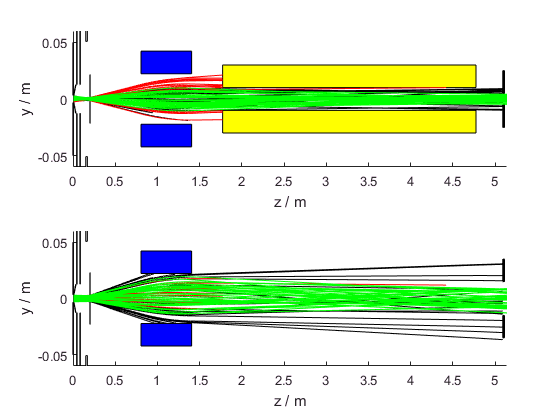

%Plot trajectories x vs z
    figure
    subplot(2,1,1)
    hold on
    %Plot cell aperture
    plot([0 0],[cell_aperture.d/2 0.05],'k','linewidth',1)
    plot([0 0],[-cell_aperture.d/2 -0.05],'k','linewidth',1)
    %Plot 4K collimator
    plot([FourK_collimator.z_1 FourK_collimator.z_2],[FourK_collimator.d_1/2 FourK_collimator.d_2/2],'k','linewidth',1)
    plot([FourK_collimator.z_1 FourK_collimator.z_2],[-FourK_collimator.d_1/2 -FourK_collimator.d_2/2],'k','linewidth',1)
    %Plot 4K shield
    rectangle('Position',[FourK_shield.z_1 FourK_shield.d_1/2 FourK_shield.z_2-FourK_shield.z_1 1],'FaceColor',[0.85 0.85 0.85])
    rectangle('Position',[FourK_shield.z_1 -FourK_shield.d_1/2-1 FourK_shield.z_2-FourK_shield.z_1 1],'FaceColor',[0.85 0.85 0.85])
    %     plot([FourK_shield.z_1 FourK_shield.z_2],[FourK_shield.d_1/2 0.05],'k','linewidth',4)
    %     plot([FourK_shield.z_1 FourK_shield.z_2],[-FourK_shield.d_1/2 -0.05],'k','linewidth',4)
    %Plot 40K shield
    rectangle('Position',[FortyK_shield.z_1 FortyK_shield.d_1/2 FortyK_shield.z_2-FortyK_shield.z_1 1],'FaceColor',[0.85 0.85 0.85])
    rectangle('Position',[FortyK_shield.z_1 -FortyK_shield.d_1/2-1 FortyK_shield.z_2-FortyK_shield.z_1 1],'FaceColor',[0.85 0.85 0.85])
    %Plot beambox exit
    rectangle('Position',[BB_exit.z_1 BB_exit.d_1/2 BB_exit.z_2-BB_exit.z_1 1],'FaceColor',[0.85 0.85 0.85])
    rectangle('Position',[BB_exit.z_1 -BB_exit.d_1/2-1 BB_exit.z_2-BB_exit.z_1 1],'FaceColor',[0.85 0.85 0.85])
    %Plot lens
    rectangle('Position',[lens.z_1 lens.d_1/2 lens.L 0.02],'facecolor','b')
    rectangle('Position',[lens.z_1 -lens.d_1/2-0.02 lens.L 0.02],'facecolor','b')
    %Plot field plate aperture
    rectangle('Position',[aperture.z_1 aperture.x_2 0.002 0.02],'facecolor','black')
    rectangle('Position',[aperture.z_1 aperture.x_1-0.02 0.002 0.02],'facecolor','black')
    %     plot([aperture.z_1 aperture.z_2],[aperture.d_1/2 0.05],'k','linewidth',1)
    %     plot([aperture.z_1 aperture.z_2],[-aperture.d_1/2 -0.05],'k','linewidth',1)
    %Plot field plates
    rectangle('Position',[field_plate.z_1 field_plate.x_2 field_plate.L 0.02],'facecolor','y')
    rectangle('Position',[field_plate.z_1 field_plate.x_1-0.02 field_plate.L 0.02],'facecolor','y')
    %Plot detection region entrance
    rectangle('Position',[detection_region.z_1 detection_region.x_2 0.02 0.02],'facecolor','black')
    rectangle('Position',[detection_region.z_1 detection_region.x_1-0.02 0.02 0.02],'facecolor','black')
    
    %Plot the trajectories
         
    z_dr = squeeze(trajectories1.detection_region(:,3,:)).';
    x_dr = squeeze(trajectories1.detection_region(:,1,:)).';
    plot(z_dr,x_dr,'k')
    
    z_lens = squeeze(trajectories1.lens(:,3,:)).';
    x_lens = squeeze(trajectories1.lens(:,1,:)).';
    plot(z_lens,x_lens,'k') 
    
    
    z_fp = squeeze(trajectories1.field_plate(:,3,:)).';
    x_fp = squeeze(trajectories1.field_plate(:,1,:)).';
    plot(z_fp,x_fp,'r')    
    
    z_detected = squeeze(trajectories1.detected(:,3,:)).';
    x_detected = squeeze(trajectories1.detected(:,1,:)).';
    plot(z_detected,x_detected,'g')
    
    
    %set axis ranges and labels
    ylim([-0.06 0.06])
    xlim([0 detection_region.z_2])
    xlabel('z / m')
    ylabel('y / m')
    hold off
    

    %Plot trajectories y vs z
    %figure(2)
    subplot(2,1,2)
    hold on
    %Plot cell aperture
    plot([0 0],[cell_aperture.d/2 0.05],'k','linewidth',1)
    plot([0 0],[-cell_aperture.d/2 -0.05],'k','linewidth',1)
    %Plot 4K collimator
    plot([FourK_collimator.z_1 FourK_collimator.z_2],[FourK_collimator.d_1/2 FourK_collimator.d_2/2],'k','linewidth',1)
    plot([FourK_collimator.z_1 FourK_collimator.z_2],[-FourK_collimator.d_1/2 -FourK_collimator.d_2/2],'k','linewidth',1)
    %Plot 4K shield
    rectangle('Position',[FourK_shield.z_1 FourK_shield.d_1/2 FourK_shield.z_2-FourK_shield.z_1 1],'FaceColor',[0.85 0.85 0.85])
    rectangle('Position',[FourK_shield.z_1 -FourK_shield.d_1/2-1 FourK_shield.z_2-FourK_shield.z_1 1],'FaceColor',[0.85 0.85 0.85])
    %     plot([FourK_shield.z_1 FourK_shield.z_2],[FourK_shield.d_1/2 0.05],'k','linewidth',4)
    %     plot([FourK_shield.z_1 FourK_shield.z_2],[-FourK_shield.d_1/2 -0.05],'k','linewidth',4)
    %Plot 40K shield
    rectangle('Position',[FortyK_shield.z_1 FortyK_shield.d_1/2 FortyK_shield.z_2-FortyK_shield.z_1 1],'FaceColor',[0.85 0.85 0.85])
    rectangle('Position',[FortyK_shield.z_1 -FortyK_shield.d_1/2-1 FortyK_shield.z_2-FortyK_shield.z_1 1],'FaceColor',[0.85 0.85 0.85])
    %Plot beambox exit
    rectangle('Position',[BB_exit.z_1 BB_exit.d_1/2 BB_exit.z_2-BB_exit.z_1 1],'FaceColor',[0.85 0.85 0.85])
    rectangle('Position',[BB_exit.z_1 -BB_exit.d_1/2-1 BB_exit.z_2-BB_exit.z_1 1],'FaceColor',[0.85 0.85 0.85])
    %Plot lens
    rectangle('Position',[lens.z_1 lens.d_1/2 lens.L 0.02],'facecolor','b')
    rectangle('Position',[lens.z_1 -lens.d_1/2-0.02 lens.L 0.02],'facecolor','b')
    %Plot field plate aperture
    rectangle('Position',[aperture.z_1 aperture.y_2 0.002 0.02],'facecolor','black')
    rectangle('Position',[aperture.z_1 aperture.y_1-0.02 0.002 0.02],'facecolor','black')
    %     plot([aperture.z_1 aperture.z_2],[aperture.d_1/2 0.05],'k','linewidth',1)
    %     plot([aperture.z_1 aperture.z_2],[-aperture.d_1/2 -0.05],'k','linewidth',1)
    %Plot field plates
    rectangle('Position',[field_plate.z_1 field_plate.y_2 field_plate.L 0.02],'facecolor','y')
    rectangle('Position',[field_plate.z_1 field_plate.y_1-0.02 field_plate.L 0.02],'facecolor','y')
    %Plot detection region entrance
    rectangle('Position',[detection_region.z_1 detection_region.y_2 0.02 0.02],'facecolor','black')
    rectangle('Position',[detection_region.z_1 detection_region.y_1-0.02 0.02 0.02],'facecolor','black')
    
    z_dr = squeeze(trajectories1.detection_region(:,3,:)).';
    y_dr = squeeze(trajectories1.detection_region(:,2,:)).';
    plot(z_dr,y_dr,'k')
    
    z_lens = squeeze(trajectories1.lens(:,3,:)).';
    y_lens = squeeze(trajectories1.lens(:,2,:)).';
    plot(z_lens,y_lens,'k')
    
    
    z_fp = squeeze(trajectories1.field_plate(:,3,:)).';
    y_fp = squeeze(trajectories1.field_plate(:,2,:)).';
    plot(z_fp,y_fp,'r')
    
    z_detected = squeeze(trajectories1.detected(:,3,:)).';
    y_detected = squeeze(trajectories1.detected(:,2,:)).';
    plot(z_detected,y_detected,'g')

    ylim([-0.06 0.06])
    xlim([0 detection_region.z_2])
    xlabel('z / m')
    ylabel('y / m')
    hold off

Now want to check what the effect of the aperture is. We'll first have the aperture right next to the beamsource and then in between the microwave regions (12.5'' from the beamsource). The idea is to loop over different aperture sizes and compare the numbers of molecules that hit each element for different sizes of aperture to find some acceptable compromise.

%Define the range of values to consider for the aperture size
aperture_sizes = [4:0.5:8]*1e-3;
n_detected = zeros(length(aperture_sizes),1);
n_fp = zeros(length(aperture_sizes),1);
n_lens = zeros(length(aperture_sizes),1);

N_molecules = 1e6;

for i = 1:length(aperture_sizes)
    %Define the coordinates of the aperture
    aperture.h = aperture_sizes(i);
    aperture.w = aperture.h/2;
    aperture.x_1 = -aperture.w/2;
    aperture.x_2 = aperture.w/2;
    aperture.y_1 = -aperture.h/2;
    aperture.y_2 = aperture.h/2;
    
    %update the beamline geometry
    beamline_geometry{5} = aperture;
    
    %call the trajectory function
    store_trajectories = false;
    tic
    [~, counts2] = trajectories_parallelized(zone_of_freezing,beamline_geometry,lens,beam,molecule,N_molecules,store_trajectories);
    toc
    
    n_detected(i) = counts2.detected;
    n_fp(i) = counts2.field_plate;
    n_lens(i) = counts2.lens;
    
end

Starting parallel pool (parpool) using the 'local' profile ...
connected to 3 workers.


Elapsed time is 50.129507 seconds.


Elapsed time is 34.820702 seconds.


Elapsed time is 32.307583 seconds.


Elapsed time is 30.768155 seconds.


Elapsed time is 31.914649 seconds.


Elapsed time is 30.400273 seconds.


Elapsed time is 29.667955 seconds.


Elapsed time is 31.142661 seconds.


Elapsed time is 31.468731 seconds.


Plot the results:

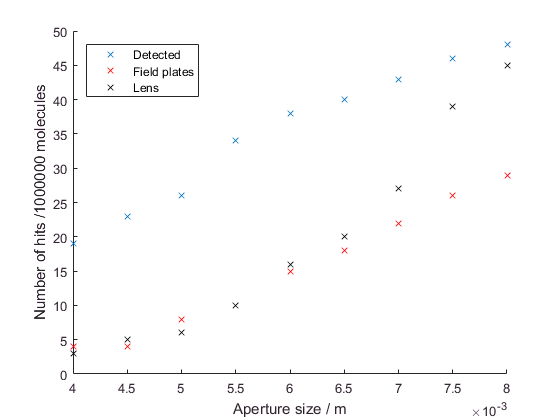

figure 
hold on
plot(aperture_sizes,n_detected,'x')
plot(aperture_sizes,n_fp,'rx')
plot(aperture_sizes,n_lens,'kx')
xlabel('Aperture size / m')
ylabel(strcat('Number of hits / ',num2str(N_molecules),' molecules'))
legend('Detected','Field plates','Lens','Location','northwest')

Next do the same thing for an aperture set in between the microwave regions:

%Define the range of values to consider for the aperture size
aperture_sizes = [8:0.5:20]*1e-3;
n_detected = zeros(length(aperture_sizes),1);
n_fp = zeros(length(aperture_sizes),1);
n_lens = zeros(length(aperture_sizes),1);

%set aperture position to be in between microwave regions
aperture.z_1 = BB_exit.z_2 + 12.5*meters_per_inch;
aperture.z_2 = aperture.z_1;

N_molecules = 1e6;

for i = 1:length(aperture_sizes)
    %Define the coordinates of the aperture
    aperture.h = aperture_sizes(i);
    aperture.w = aperture.h/2;
    aperture.x_1 = -aperture.w/2;
    aperture.x_2 = aperture.w/2;
    aperture.y_1 = -aperture.h/2;
    aperture.y_2 = aperture.h/2;
    
    %update the beamline geometry
    beamline_geometry{5} = aperture;
    
    %call the trajectory function
    store_trajectories = false;
    tic
    [~, counts2] = trajectories_parallelized(zone_of_freezing,beamline_geometry,lens,beam,molecule,N_molecules,store_trajectories);
    toc
    
    n_detected(i) = counts2.detected;
    n_fp(i) = counts2.field_plate;
    n_lens(i) = counts2.lens;
    
end

Elapsed time is 30.542259 seconds.


Elapsed time is 29.199227 seconds.


Elapsed time is 30.015574 seconds.


Elapsed time is 29.688407 seconds.


Elapsed time is 29.268030 seconds.


Elapsed time is 29.213939 seconds.


Elapsed time is 29.399830 seconds.


Elapsed time is 30.110311 seconds.


Elapsed time is 29.912103 seconds.


Elapsed time is 29.755252 seconds.


Elapsed time is 30.082046 seconds.


Elapsed time is 30.414559 seconds.


Elapsed time is 30.640379 seconds.


Elapsed time is 29.669047 seconds.


Elapsed time is 31.402534 seconds.


Elapsed time is 31.638889 seconds.


Elapsed time is 31.915411 seconds.


Elapsed time is 30.859739 seconds.


Elapsed time is 30.916825 seconds.


Elapsed time is 31.216963 seconds.


Elapsed time is 32.785084 seconds.


Elapsed time is 31.601156 seconds.


Elapsed time is 33.217267 seconds.


Elapsed time is 30.982151 seconds.


Elapsed time is 32.713324 seconds.


Plot the results:

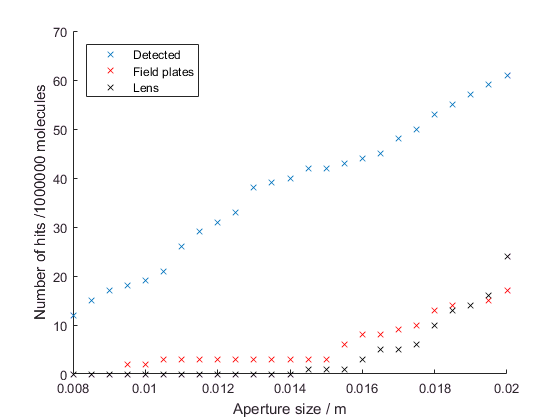

figure 
hold on
plot(aperture_sizes,n_detected,'x')
plot(aperture_sizes,n_fp,'rx')
plot(aperture_sizes,n_lens,'kx')
xlabel('Aperture size / m')
ylabel(strcat('Number of hits / ',num2str(N_molecules),' molecules'))
legend('Detected','Field plates','Lens','Location','northwest')